clear all
MouseToAvoid=[560,117,431]; % mice with noisy data to exclude
SessionNames={'UMazeCond_EyeShock', 'UMazeCondBlockedShock_EyeShock', 'UMazeCondBlockedSafe_EyeShock'};
[SpecData.EyeShock,NumRip.EyeShock,DurPer.EyeShock,Spectrogram.EyeShock,GammaOB.EyeShock,HRInfo.EyeShock]=GetSpectraDataForTwoFreezingOverview(SessionNames);

SessionNames={'UMazeCond'};
[SpecData.PAG,NumRip.PAG,DurPer.PAG,Spectrogram.PAG,GammaOB.PAG,HRInfo.PAG]=GetSpectraDataForTwoFreezingOverview(SessionNames);
SessionNames={'UMazeCondNight'};
[SpecData.PAGNight,NumRip.PAGNight,DurPer.PAGNight,Spectrogram.PAGNight,GammaOB.PAGNight,HRInfo.PAGNight]=GetSpectraDataForTwoFreezingOverview(SessionNames);



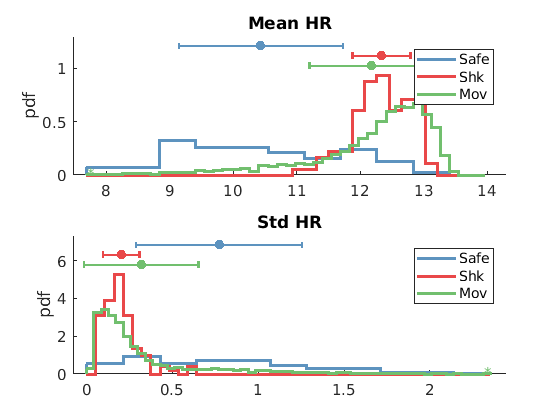

AllSafeHR=[];AllShockHR=[];AllMovHR=[];
AllSafeHRStd=[];AllShockHRStd=[];AllMovHRStd=[];

for mm=[3,5]
    for k=1:9
        AllShockHR=[AllShockHR,HRSliceBySlice.Shk{mm,k}.MeanHR];
        AllSafeHR=[AllSafeHR,HRSliceBySlice.Sf{mm,k}.MeanHR];
        AllSafeHRStd=[AllSafeHRStd,HRSliceBySlice.Sf{mm,k}.StdHR];
        AllShockHRStd=[AllShockHRStd,HRSliceBySlice.Shk{mm,k}.StdHR];
        AllMovHR=[AllMovHR,HRSliceBySlice.Mv{mm,k}.MeanHR];
        AllMovHRStd=[AllMovHRStd,HRSliceBySlice.Mv{mm,k}.StdHR];
    end
end

figure
subplot(211)
nhist({AllSafeHR,AllShockHR,AllMovHR});
legend('Safe','Shk','Mov')
title('Mean HR')
subplot(212)
nhist({AllSafeHRStd,AllShockHRStd,AllMovHRStd});
legend('Safe','Shk','Mov')
title('Std HR')


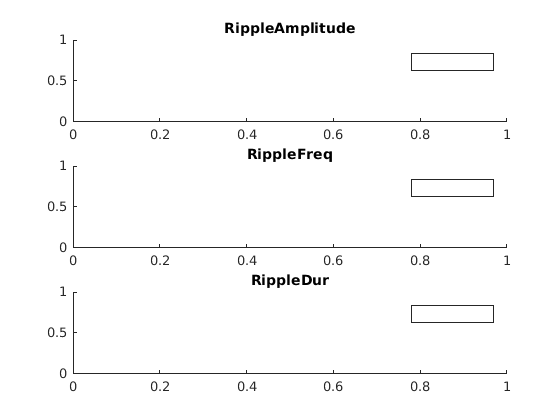

ShkSf={'Shock','Safe'};
for ss=1:2
    for mm=1:5
        SpectrogramFinal.(ShkSf{ss}){mm}=zeros(94,201);
        for sess=1:9
            if not(isnan(NumRip.(ShkSf{ss}).Sess(mm,sess))) & NumRip.(ShkSf{ss}).Sess(mm,sess)>0
                SpectrogramFinal.(ShkSf{ss}){mm}=SpectrogramFinal.Shock{mm}+Spectrogram.(ShkSf{ss}){mm,sess}*NumRip.(ShkSf{ss}).Sess(mm,sess);
            end
            SpectrogramFinal.(ShkSf{ss}){mm}=SpectrogramFinal.(ShkSf{ss}){mm}/nansum(NumRip.(ShkSf{ss}).Sess(mm,:));
        end
    end
    
end

clear all
SessionNames={'ExtinctionBlockedShock_EyeShock' 'ExtinctionBlockedSafe_EyeShock' };

ShkSf={'Shock','Safe'};
for mm=1:5
    for ss=1:length(SessionNames)
        SpecData.(ShkSf{ss}){mm}=[];
        SpecDataH.(ShkSf{ss}){mm}=[];
        SpecDataHLo.(ShkSf{ss}){mm}=[];
        Files=PathForExperimentsEmbReact(SessionNames{ss});
        MouseToAvoid=[560]; % mice with noisy data to exclude
        Files=RemoveElementsFromDir(Files,'nmouse',MouseToAvoid);
        
        for c=1
            cd(Files.path{mm}{c})
            load('behavResources.mat')
            dt=median(diff(Range(Behav.Vtsd,'s')));
            if not(isempty(Behav.FreezeAccEpoch))
                FreezeEpoch=Behav.FreezeAccEpoch;
            else
                FreezeEpoch=Behav.FreezeEpoch;
            end
            load('B_Low_Spectrum.mat')
            fLow=Spectro{3};
            Sptsd=tsd(Spectro{2}*1e4,Spectro{1});
            load('H_Low_Spectrum.mat')
            SptsdHLo=tsd(Spectro{2}*1e4,Spectro{1});
            clear TotalNoiseEpoch smooth_ghi
            load('StateEpochSB.mat','TotalNoiseEpoch','smooth_ghi')
            RemovEpoch=TotalNoiseEpoch;
            
            if exist('ChannelsToAnalyse/dHPC_rip.mat')>0
                load('H_VHigh_Spectrum.mat')
                SptsdH=tsd(Spectro{2}*1e4,Spectro{1});
                fHigh=Spectro{3};
                try
                    load('RipplesSleepThresh.mat')
                    RiptsdSL=ts(Rip(:,2)*1e4);
                    load('Ripples.mat')
                    Riptsd=ts(Rip(:,2)*1e4);
                catch
                    disp('ripple problem')
                    Riptsd=ts(0.1*1e4);
                    RiptsdSL=ts(0.1*1e4);
                end
            end
            
            
            LitEp=dropShortIntervals(Behav.FreezeEpoch-RemovEpoch,3*1e4);
            GammaOB.(ShkSf{ss})(mm,c)=nanmean(Data(Restrict(smooth_ghi,LitEp)));
            SpecData.(ShkSf{ss}){mm}=[SpecData.(ShkSf{ss}){mm};Data(Restrict(Sptsd,LitEp))];
            SpecDataHLo.(ShkSf{ss}){mm}=[SpecDataHLo.(ShkSf{ss}){mm};Data(Restrict(SptsdHLo,LitEp))];
            ttemp=nansum(Stop(LitEp,'s')-Start(LitEp,'s'));
            if isempty(ttemp)
                DurFzTime.(ShkSf{ss})(mm,c)=0;
            else
                DurFzTime.(ShkSf{ss})(mm,c)=nansum(Stop(LitEp,'s')-Start(LitEp,'s'));
            end
            if exist('ChannelsToAnalyse/dHPC_rip.mat')>0
                SpecDataH.(ShkSf{ss}){mm}=[SpecDataH.(ShkSf{ss}){mm};Data(Restrict(SptsdH,LitEp))];
                if not(isempty(Start(LitEp)))
                    NumRip.(ShkSf{ss}).Sess(mm,c)=length(Range(Restrict(Riptsd,LitEp)));
                    DurPer.(ShkSf{ss}).Sess(mm,c)=nansum(Stop(LitEp,'s')-Start(LitEp,'s'));
                    NumRip.(ShkSf{ss}).Sleep(mm,c)=length(Range(Restrict(RiptsdSL,LitEp)));
                    DurPer.(ShkSf{ss}).Sleep(mm,c)=nansum(Stop(LitEp,'s')-Start(LitEp,'s'));
                    
                else
                    NumRip.(ShkSf{ss}).Sess(mm,c)=NaN;
                    DurPer.(ShkSf{ss}).Sess(mm,c)=NaN;
                    NumRip.(ShkSf{ss}).Sleep(mm,c)=NaN;
                    DurPer.(ShkSf{ss}).Sleep(mm,c)=NaN;
                end
            else
                NumRip.(ShkSf{ss}).Sess(mm,c)=NaN;
                DurPer.(ShkSf{ss}).Sess(mm,c)=NaN;
                NumRip.(ShkSf{ss}).Sleep(mm,c)=NaN;
                DurPer.(ShkSf{ss}).Sleep(mm,c)=NaN;
            end
            
            if exist('ChannelsToAnalyse/EKG.mat')
                load('HeartBeatInfo.mat')
                [HRInfo.(ShkSf{ss}){mm,c+(ss-1)*3},HRSliceBySlice{ss}{mm,c+(ss-1)*3},SliceDur{ss}{mm,c+(ss-1)*3}]=CharacterizeHeartRateEpoch(EKG,LitEp,2);
            end
        end
        
    end
end
disp('OK')


for mm=1:5
    AllShock(mm,:)=mean(SpecData.Shock{mm});
    AllSafe(mm,:)=mean(SpecData.Safe{mm});
    AllShockH(mm,:)=mean(SpecDataH.Shock{mm});
    AllSafeH(mm,:)=mean(SpecDataH.Safe{mm});
    AllShockHLo(mm,:)=mean(SpecDataHLo.Shock{mm});
    AllSafeHLo(mm,:)=mean(SpecDataHLo.Safe{mm});
end
figure
[hl,hp]=boundedline(fLow,nanmean(AllShock),[stdError(AllShock);stdError(AllShock)]','r','alpha'),hold on
[hl,hp]=boundedline(fLow,nanmean(AllSafe),[stdError(AllSafe);stdError(AllSafe)]','b','alpha');
title('OB')
figure
[hl,hp]=boundedline(fHigh,nanmean(log(AllShockH)),[stdError(log(AllShockH));stdError(log(AllShockH))]','r','alpha');hold on
[hl,hp]=boundedline(fHigh,nanmean(log(AllSafeH)),[stdError(log(AllSafeH));stdError(log(AllSafeH))]','b','alpha');
title('HPC')
figure
[hl,hp]=boundedline(fLow,nanmean(log(AllShockHLo)),[stdError(log(AllShockHLo));stdError(log(AllShockHLo))]','r','alpha');hold on
[hl,hp]=boundedline(fLow,nanmean(log(AllSafeHLo)),[stdError(log(AllSafeHLo));stdError(log(AllSafeHLo))]','b','alpha');
title('HPC')
figure
subplot(121)
PlotErrorBarN([([NumRip.Shock.Sess./DurPer.Shock.Sess]');([NumRip.Safe.Sess./DurPer.Safe.Sess]')]',0,1);
set(gca,'XTick',[1,2],'XTickLabel',{'Shock','Safe'})
ylabel('Ripples per sec')
title('Sess by sess calibration')
subplot(122)
PlotErrorBarN([([NumRip.Shock.Sleep./DurPer.Shock.Sleep]');([NumRip.Safe.Sleep./DurPer.Safe.Sleep]')]',0,1);
ylabel('Ripples per sec')
set(gca,'XTick',[1,2],'XTickLabel',{'Shock','Safe'})
title('Calibration on closest sleep')

figure
PlotErrorBarN([(GammaOB.Shock');(GammaOB.Safe')]');
ylabel('Gamma Power')
set(gca,'XTick',[1,2],'XTickLabel',{'Shock','Safe'})

figure,
PlotErrorBarN([DurPer.Shock.Sess,DurPer.Safe.Sess],0);
